BIOLOGISTS PROBLEM

Soln: The given example can be modelled in terms of linear function c(n)= b+mt

Here b=chirps per second, t=temp, m=slope=change in degree F for every chirp per minute change 

syms m b t 
temp= [50 55 60 65 70 75 80 85 90]% temp in deg

temp =     50    55    60    65    70    75    80    85    90


temp 50 55 60 65 70 75 80 85 90

chirp_rate= [20 46 79 91 113 140 173 198 211]%chirps/min

chirp_rate =     20    46    79    91   113   140   173   198   211


chirp_rate=  20 46 79 91 113 140 173 198 211

fig3=figure;
scatter(temp, chirp_rate, 'ro')
%(b) chirp rate as a fun of temp
c(t)=b+m*t

$$c(t) = b+m\,t$$

eqns= [c(50)==20  c(90)==211]

$$eqns = \left(\begin{array}{cc} b+50\,m=20 & b+90\,m=211 \end{array}\right)$$

eqns = (b+50m=20  b+90m=211)

[m, b]=solve(eqns, [m b])

$$m = \frac{191}{40}$$

$$b = -\frac{875}{4}$$

m=191/40, b=-875/4

c(t)= subs(c(t))

$$c(t) = \frac{191\,t}{40}-\frac{875}{4}$$

c(t) = 191t/40-875/4

%(c)  estimation 
C_pred= round(c(100))

$$C\_pred = 259$$

c_pred = 259

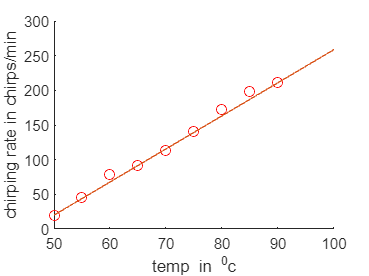

%(d) Graph of model 
hold on
fplot(c(t), [50 100])
xlabel('temp in ^0c')
ylabel('chirping rate in chirps/min')
hold off